Consider the problem of interpolating $\log(x)$ at these nodes:

t = [ 1, 1.6, 1.9, 2.7, 3 ];

Here $n=4$ and $f^{(5)}(\xi) = 4!/\xi^5$. For $\xi\in[1,3]$ we can say that $|f^{(5)}(\xi)| \le 4!$. Hence


$$ |f(x)-p(x)| \le \frac{1}{5} \Phi(x).$$


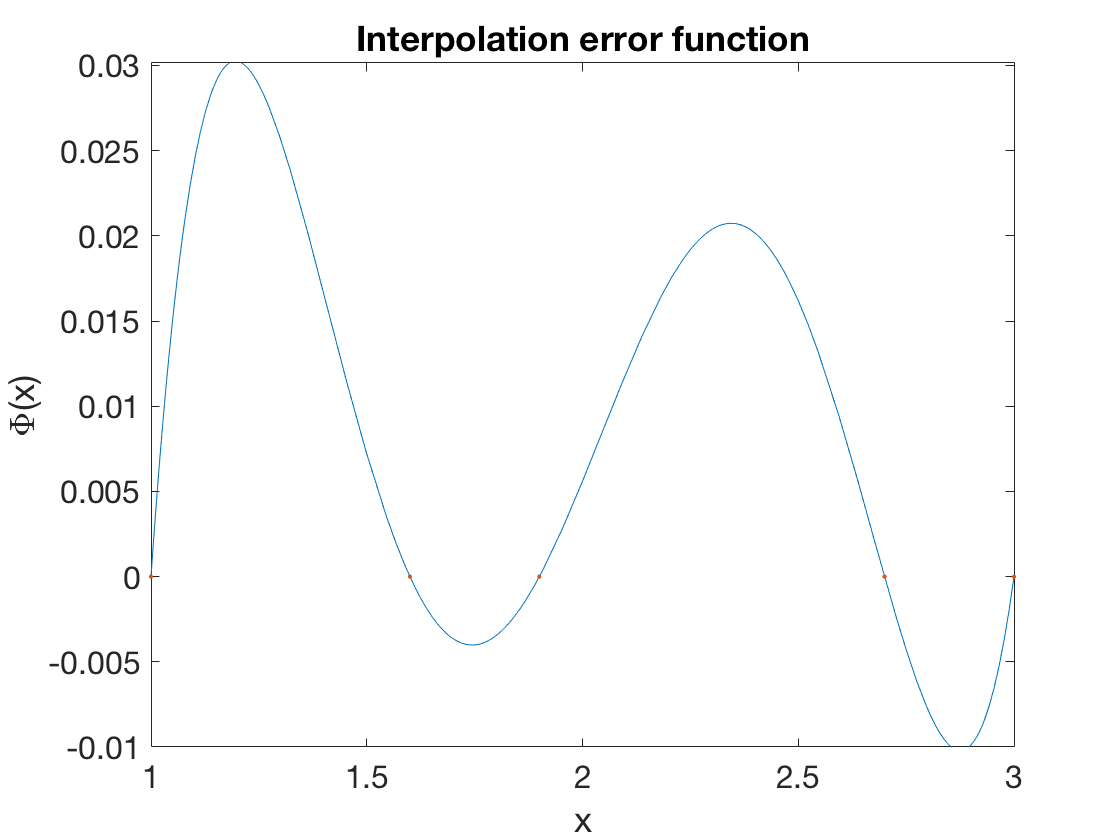

Phi = @(x) prod(x-t);
fplot(@(x) Phi(x)/5,[1 3])
hold on, plot(t,0*t,'.')
xlabel('x'), ylabel('\Phi(x)')   % ignore this line
title('Interpolation error function')   % ignore this line

The error bound has one local extreme point between each consecutive pair of nodes.